clear;
profile on;

## Load Images

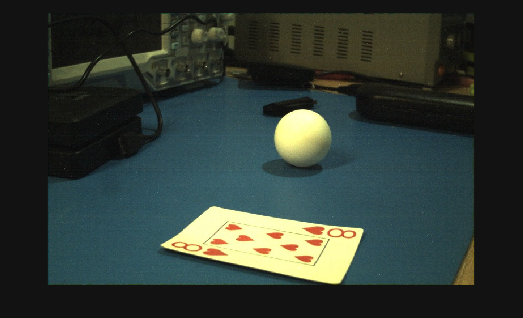

rightImage = imread("images\right5.jpg");
imshow(rightImage)

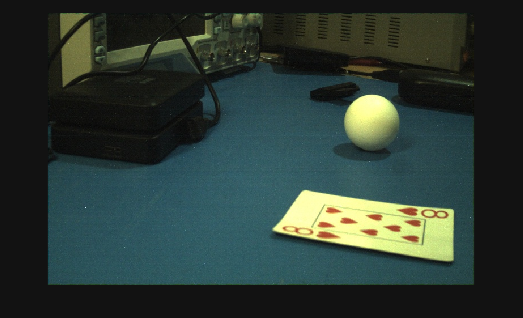


leftImage= imread("images\left5.jpg");
imshow(leftImage)

## Binarize

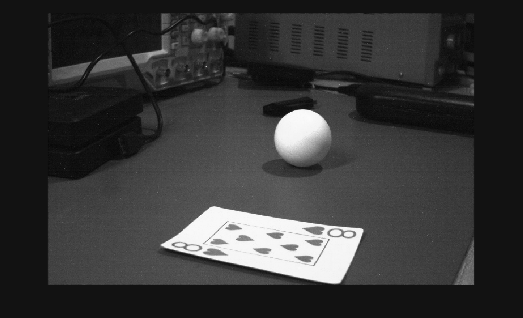

grayRight = rgb2gray(rightImage);
imshow(grayRight)

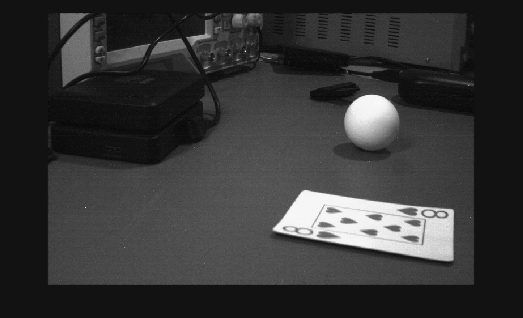

grayLeft =rgb2gray(leftImage);
imshow(grayLeft)

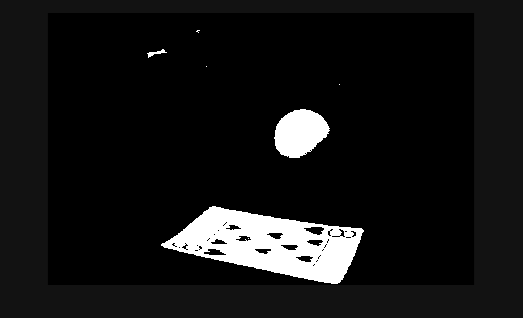


rightBW = imbinarize(grayRight);
imshow(rightBW)

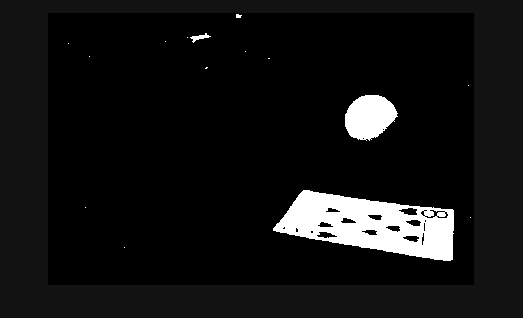

leftBW = imbinarize(grayLeft);
imshow(leftBW)

## Identify largest blobs

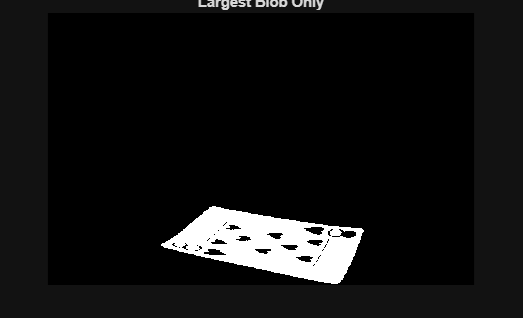

ccR = bwconncomp(rightBW);
stats = regionprops(ccR, 'Area');
areas = [stats.Area];
[~, idx] = max(areas);

rightBW_largest = false(size(rightBW));
rightBW_largest(ccR.PixelIdxList{idx}) = true;

figure;
imshow(rightBW_largest);
title('Largest Blob Only');